**Генерация функций с сохранением в отдельный файл для оптимизации критерия стабильности **

Кривая равновесия (f_1 = 0)

% clear all;
% 
% syms a b c l_1 l_2 psi theta_2 theta_2i k_2i
% f = h(a,b,c,l_1,psi,theta_2)*cos(theta_2);
% matlabFunction(f,'File','equilibriumCurve');

Генерация целевой функции для поиска Paradoxical point в символьной форме

% clear all;
% syms k_2 theta_2 k_2i theta_2i a b c l_1 psi;
% 
% f_1 = equilibriumCurve(a, b, c, l_1, psi, theta_2); % k_2 = f(theta_2)
% f_2 = solve(singlePointContactTrajectory(k_2, theta_2, k_2i, theta_2i, l_1), k_2); % k_2 = f(theta_2)
% f_2 = f_2(2);
% 
% f_1d = diff(f_1, theta_2);
% f_2d = diff(f_2, theta_2);
% 
% % Условие касания двух кривых: значения кривых совпадают в точке касания и
% % производные в точке касания равны
% F1 = f_1 - f_2;
% F2 = f_1d - f_2d;
% 
% % Условие, что точка касания точно принадлежит кривой
% F3 = k_2 - f_2;
% 
% f = [F1; F2; F3];
% 
% matlabFunction(f,'File','objParadoxical');

Определение координат Paradoxical point

% clear all;
% 
% a = 1; b = 1; c = 1/3;
% l_1 = 1; l_2 = 2/3;
% psi = pi/2;
% 
% paradoxicalCoord(a, b, c, l_1, psi)

Определение критерия стабильности для заданной геометрии пальца

% clear all;
% 
% a = 1.8162; b = 6.4299; c = 2.3660;
% l_1 = 4; l_2 = l_1;
% psi = pi/2;
%     
% stabilityCriterion(a, b, c, l_1, l_2, psi)

Постановка задачи оптимизации геометрии пальца с целью максимизации критерия стабильности

clear all;

l_1 = 4; l_2 = l_1; psi = pi/2;

% theta_2_min = 0;
% theta_2_max = pi/2;

% Оптимизация на основе Problem-based approach
a = optimvar('a', 'LowerBound', 1, 'UpperBound', 3);
b = optimvar('b', 'LowerBound', 4, 'UpperBound', 9);
c = optimvar('c', 'LowerBound', 1, 'UpperBound', 2.5);

% Конвертация функции подсчета критерия стабильности в формат целевой функции для оптимизации
obj = fcn2optimexpr(@(a, b, c)stabilityCriterion(a, b, c, l_1, l_2, psi), a, b, c);


No solution found.

fsolve stopped because the last step was ineffective. However, the vector of function
values is not near zero, as measured by the value of the function tolerance. 

<stopping criteria details>


prob = optimproblem("Objective", obj);%, 'ObjectiveSense', 'max');

% Начальные условия
x0.a = a.LowerBound + (a.UpperBound-a.LowerBound)*rand();
x0.b = b.LowerBound + (b.UpperBound-b.LowerBound)*rand();
x0.c = c.LowerBound + (c.UpperBound-c.LowerBound)*rand()

x0 = struct with fields:
    a: 1.8155
    b: 4.1819
    c: 2.1192


% Ограничения

% Условия некомплесности кривой равновесия k_2=f(theta_2)
bfun1 = 4*a^2*b^2-(l_1^2+2*l_1*c-a^2-b^2+c^2)^2; 
bfun2 = 4*a^2*b^2-(l_1^2-a^2-b^2+c^2)^2; 

% Условие непревышения k_2 <= l_2
bfun3 = fcn2optimexpr(@(a, b, c)equilibriumCurveRestriction(a, b, c, l_1, psi), a, b, c);

% Условие равенства k_2(theta_2 = 0) = l_2
% bfun4 = fcn2optimexpr(@(a, b, c)equilibriumCurve(a, b, c, l_1, psi, 0), a, b, c);

prob.Constraints.cons1 = bfun1 >= 0;
prob.Constraints.cons2 = bfun2 >= 0;
prob.Constraints.cons3 = bfun3 <= l_2;
% prob.Constraints.cons4 = bfun4 - l_2 == 0;

% show(prob);

% Решение с помощью GA на основе Problem-based Approach с
% распараллеливанием вычислений
parpool;

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 12).


Solving problem using ga.

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the 

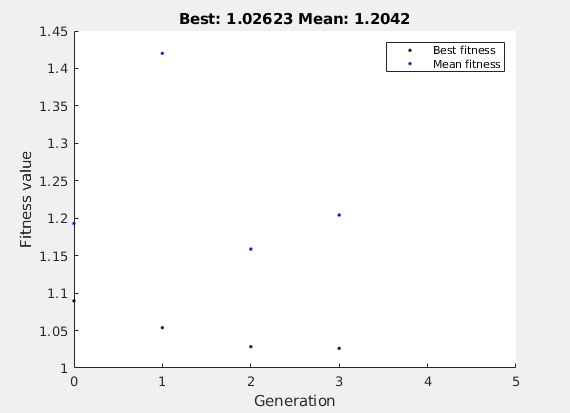

options = optimoptions(@ga, 'PlotFcn',{@gaplotbestf});
options = optimoptions(options, 'MaxGenerations', 5, 'MaxStallGenerations', 5, 'PopulationSize', 15, 'UseParallel', true);

rng default % For reproducibility
tic;
[sol,fval] = solve(prob, "Solver", "ga", 'Options', options);

toc

Elapsed time is 503.155608 seconds.


delete(gcp('nocreate'));

Визуализация найденного решения

% Подстановка оптимизированных геометричеких параметров
a = sol.a;
b = sol.b;
c = sol.c;

% Параметры графика для отображения результата
f1 = figure;
hold on;
grid on;
title('Плоскость состояния захвата (k_2,\theta_2)');
xlabel('k_2 (cm)');
ylabel('\theta_2 (rad)');
axis ij; % Разворот оси y - смещение начала координат

% ax=gca;
% ax.XTickLabel = ax.XTick/l_2; % Изменение масштаба по оси Х в 1/l_2 раз
% xlim([0 l_2]);

theta_2_min = 0;
theta_2_max = pi/2-0.01;
theta_2 = linspace(theta_2_min, theta_2_max, 50);
k_2_min = 0.001;
k_2_max = l_2;

Отрисовка кривой равновесия

k_2 = equilibriumCurve(a, b, c, l_1, psi, theta_2);
plot(k_2,theta_2, 'Marker','.','Color','r');

Поиск и отрисовка контактной траектории, соответствующей найденным условиям 

[out, fval] = paradoxicalCoord(a, b, c, l_1, psi);


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


k_2_tang = out(1); theta_2_tang = out(2); % Координаты Paradoxical point
k_2i = out(3);     theta_2i = 0; % Н.У. контактной траектории

plotSinglePointContactTrajectory(f1, k_2i, theta_2i, l_1, l_2);

Отображение Paradoxical point

plot(out(1), out(2), '+b', 'LineWidth', 2);

Отображение устойчивых и неустойчивых зон

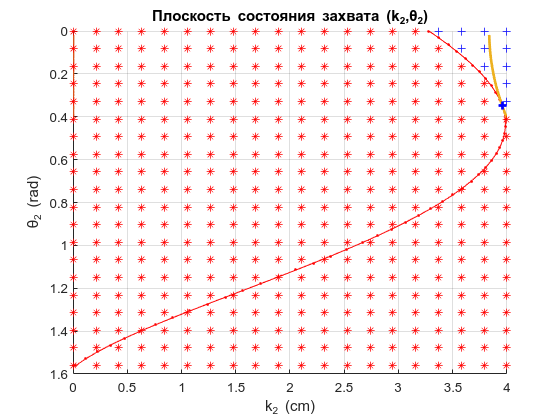

plotStableZones(f1, a, b, c, l_1, psi, k_2i, theta_2i, theta_2_tang, theta_2_min, theta_2_max, k_2_min, k_2_max);